## 加载电池数据

clear
clc
addpath('Capacity data\');
addpath('EIS data\');
% CurrentFolder = pwd;
% addpath(genpath(CurrentFolder));
filenames = {'EIS_state_V_35C02.txt','Data_Capacity_35C02.txt'};
FileNum = length(filenames);
EIS_Data = importdata(filenames{1});
CapacityData = importdata(filenames{2});
% EIS_Data = EIS_Data.data;
CapacityData = CapacityData.data;
CycleNum = min(max(EIS_Data(:,2)),max(CapacityData(:,2)));
Capacity = cell(1,CycleNum);
EISData = cell(1,CycleNum);

for kk = 1:CycleNum
    z = find(EIS_Data(:,2)==kk);
    z1 = find(CapacityData(:,2)==kk-1);
    SubEISData = EIS_Data(z,4:7);
    SubEISData = mat2cell(SubEISData,60,4);
    SubCapacity = CapacityData(z1,:);
    SubCapacity= SubCapacity(end,end);
    Capacity(kk) = num2cell(SubCapacity);
    EISData(kk) = SubEISData;
end
k=0.6;
TrainX = EISData(1:round(k*CycleNum));
TrainY = Capacity(1:round(k*CycleNum));
TestX = EISData(1+round(k*CycleNum):end);
TestY = Capacity(1+round(k*CycleNum):end);

## 设置网络结构

InputSize = [60,4,1];
FilterSize = [3,3] ;Filters = 15;
layers = [
sequenceInputLayer(InputSize,Name='input')
convolution2dLayer(FilterSize,Filters,Padding="same",Name='con2d-1')
averagePooling2dLayer([3,3])
reluLayer
% convolution2dLayer(FilterSize,2*Filters,Padding="same",Name='con2d-2')
% reluLayer
flattenLayer(Name='flatten')
% selfAttentionLayer(5,25,Name='AttentionMask');%"AttentionMask","causal",
selfAttentionLayer(7,35)
reluLayer
fullyConnectedLayer(320,Name='fc1')
reluLayer
fullyConnectedLayer(160,Name='fc2');reluLayer
fullyConnectedLayer(80,Name='fc3');reluLayer
fullyConnectedLayer(1,Name='fc4')
regressionLayer
];
graph = layerGraph(layers);


## 设置训练选项参数

options = trainingOptions("adam",...
    "Plots",'none',...
    'MaxEpochs',30,...
    'Shuffle','every-epoch',...
    'InitialLearnRate',0.01,...
    'LearnRateSchedule','piecewise',...
    'GradientThreshold',1,...
    'LearnRateDropPeriod',15,...
    'MiniBatchSize',16,...
    'LearnRateDropFactor',0.2,'ExecutionEnvironment','auto',...
     'ValidationData',{TestX,TestY})%,'ValidationPatience',9);%

options =   TrainingOptionsADAM - 属性:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 30
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 16
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {{1×127 cell}  {1×127 cell}}
       

## 训练模型

model  = trainNetwork(TrainX,TrainY,graph,options);

在单 CPU 上训练。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：００　｜　　　　　　３４．２４　｜　　　　　２６．２３　｜　５８６．１００３　｜　３４４．０８１４　｜　　０．０１００　｜
｜　　　５　｜　　　５０　｜　　　　　００：００：００　｜　　　　　　１２．２０　｜　　　　　　７．５６　｜　７４．４２７７　｜　２８．５９６４　｜　　０．０１００　｜
｜　　１０　｜　　１００　｜　　　　　００：００：０１　｜　　　　　　　６．８４　｜　　　　　　７．７０　｜　２３．３９０３　｜　２９．６５４４　｜　　０．０１００　｜
｜　　１４　｜　　１５０　｜　　　　　００：００：０２　｜　　　　　　　２．６８　｜　　　　　　０．３４　｜　　３．６００５　｜　０．０５９２　｜　　０．０１００　｜
｜　　１９　｜　　２００　｜　　　　　００：００：０３　｜　　　　　　　１．５９　｜　　　　　　１．４８　｜　　１．２６２８　｜　１．０９４９　｜　　０．００２０　｜
｜　　２３　｜　　２５０　｜　　　　　００：００：０５　｜　　　　　　　０．３６　｜　　　　　　０．７９　｜　　０．０６４４　｜　０．３１５５　｜　　０．００２０　｜
｜　　２８　｜　　３００　｜　　　　　００：００：０６　｜　　　　　　　０．３５　｜　　　　　　０．８７　｜　　０．０５９５　｜　０．３７７５　｜　　０．００２０　｜
｜　　３０　｜　　３３０　｜　　　　　００：００：０６　｜　　　　　　　０．５１　｜　　　　　　０．２１　｜　　０．１

## **预测数据**

predictTrain = predict(model,TrainX)';
predictTest = predict(model,TestX)';
TrainSOH = (cell2mat(TrainY))./45;
TestSOH = (cell2mat(TestY))./45;
PredictTrainSOH = (cell2mat(predictTrain))./45;
PredictTestSOH = (cell2mat(predictTest))./45;
PredictTestSOH1 = movmean(PredictTestSOH,5);
error = TestSOH-PredictTestSOH; error1 = TestSOH-PredictTestSOH1;
RMSE = rms(error);disp(['RMSE为',num2str(RMSE)]);RMSE1 = rms(error1)

RMSE为0.004625


RMSE1 = single
0.0036

## 绘图

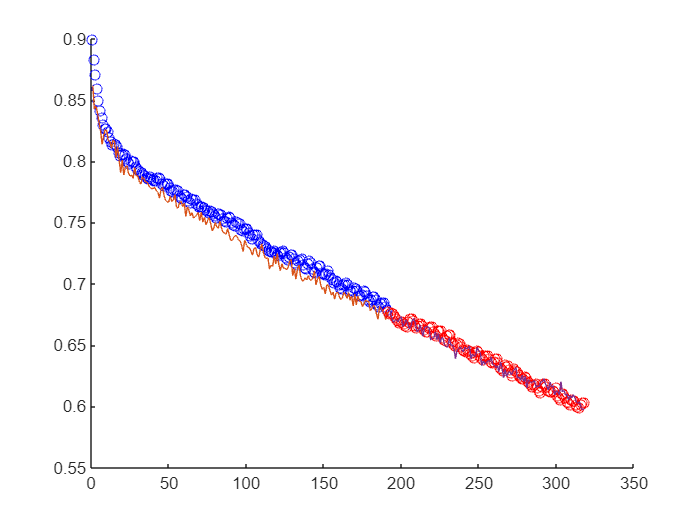

figure; hold on;
plot(1:round(k*CycleNum),TrainSOH,'bo',1:round(k*CycleNum),PredictTrainSOH);
plot(round(k*CycleNum)+1:CycleNum,TestSOH,'ro',round(k*CycleNum)+1:CycleNum,PredictTestSOH);

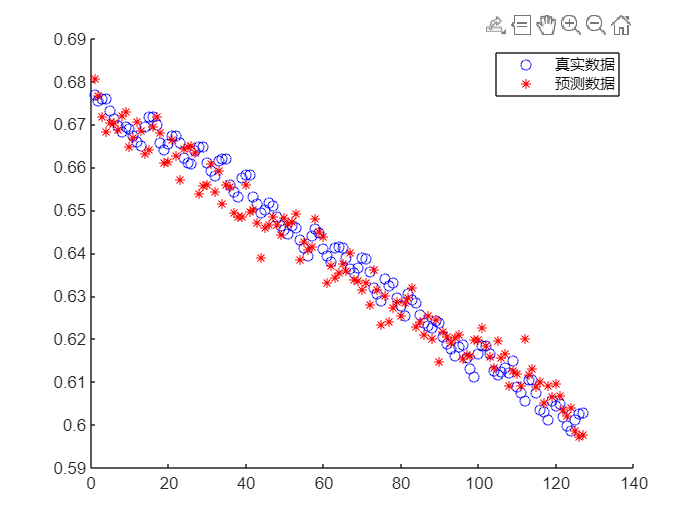

figure; hold on; 
plot(TestSOH,'bo');
plot(PredictTestSOH,'r*');
legend('真实数据','预测数据');

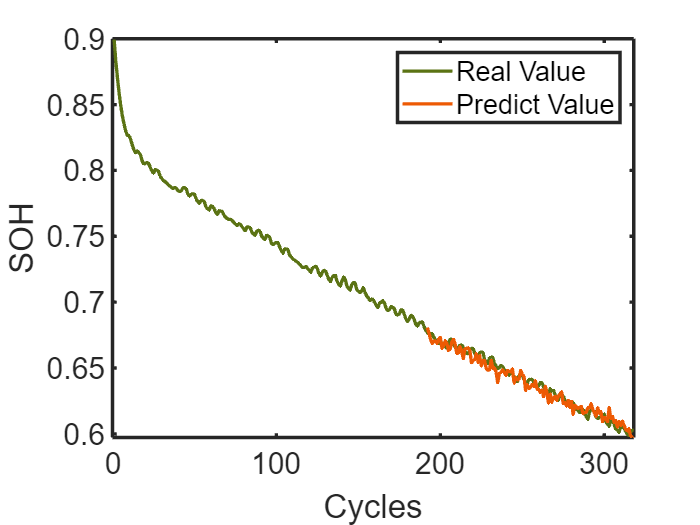

Capacity = cell2mat(Capacity);
figure; hold on; box on;
plot(Capacity./45,'LineWidth',2,'color',[91/256,115/256,20/256])
plot(round(k*CycleNum)+1:CycleNum,PredictTestSOH,'LineWidth',2,'color',[238,90,4]./256);
xlabel('Cycles');ylabel('SOH')
legend("Real Value","Predict Value")
set(gca,'FontSize',18,"LineWidth",2);

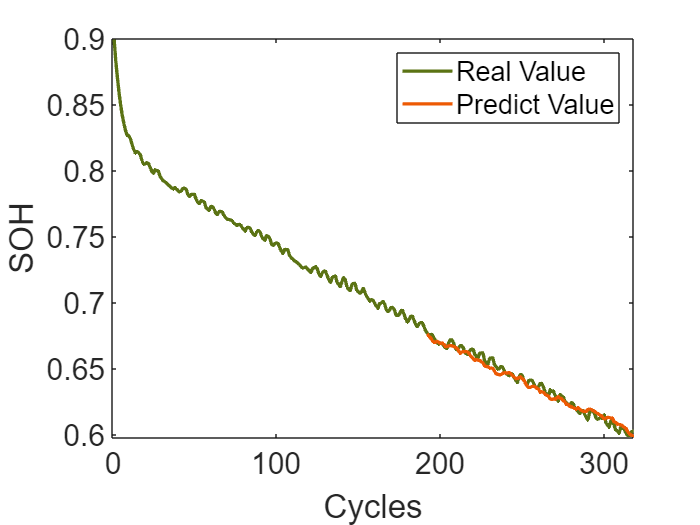

figure;hold on;box on;
plot(Capacity./45,'LineWidth',2,'color',[91/256,115/256,20/256])
plot(round(k*CycleNum)+1:CycleNum,PredictTestSOH1,'LineWidth',2,'color',[238,90,4]./256);
xlabel('Cycles');ylabel('SOH')
legend("Real Value","Predict Value")
set(gca,'FontSize',18);

% 添加放大区域
% zp = BaseZoom();
% zp.plot;
% figure;hold on;
% plot(TestSOH,PredictTestSOH1,'LineWidth',2,'color',[70,133,133]./256);

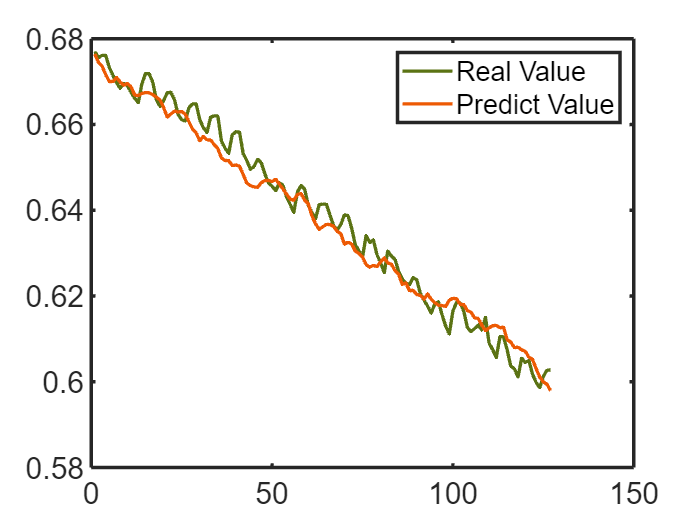

figure; hold on; box on;
plot(TestSOH, 'LineWidth',2,'Color',[91/256,115/256,20/256])
plot(PredictTestSOH1,'LineWidth',2,'Color',[238,90,4]./256);
set(gca,'Fontsize',18,"LineWidth",2)
legend('Real Value','Predict Value'); 

% xlswrite('CNNAttentionResult35C02.xlsx',PredictTestSOH');
% writematrix(Capacity','CNNAttentionResult35C02.xlsx','Sheet',2);
